MK = [mapping_kalman(); mapping_kalman();mapping_kalman();mapping_kalman()]

MK =   4×1 mapping_kalman array with properties:

    state
    cov
    p_tag_front
    p_tag_back
    UWB_cov
    k_anchor



for i = 1:4
    MK(i).UWB_cov = eye(2) * 0.1.^2;
    MK(i).k_anchor = i;
    MK(i).p_tag_front = [0.2; 0];
    MK(i).p_tag_back = [-0.2; 0];
end

state_history = []


state_history =

     []




for n = 1:width(robot_state_history)
    meas_UWB = [dist_front_history(:,n); dist_back_history(:,n)];
    robot_state = robot_state_history(:,n);
    for i = 1:4
        [state_c, cov_c] = MK(i).UWB_meas(meas_UWB, robot_state);
        state_history(:,n,i) = state_c;
    end
end

state_history(:,end,:)

ans = ans(:,:,1) =

    0.0029
   -0.0133
    3.0000


ans(:,:,2) =

    9.1583
   -0.5909
    4.1329


ans(:,:,3) =

    8.4606
    6.0334
    7.4828


ans(:,:,4) =

    0.0260
    9.9403
    3.1803


anchor_mat

anchor_mat =      0    10    10     0
     0     0    10    10
     3     3     3     3


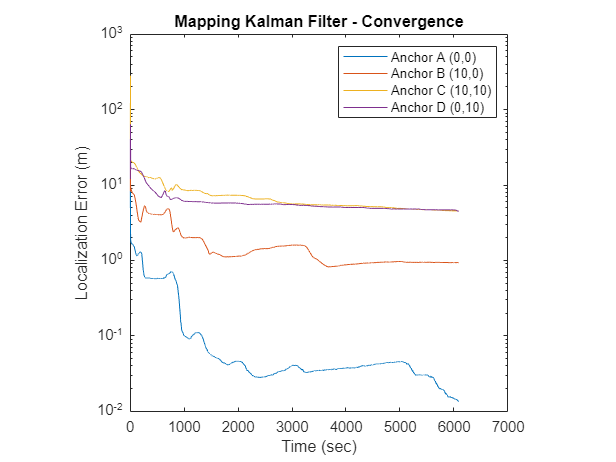

tt = (1:length(state_history))-1 * (1/15);
semilogy(tt, (vecnorm(state_history(:,:,1) - anchor_mat(:,1)))); hold on
semilogy(tt, (vecnorm(state_history(:,:,2) - anchor_mat(:,2))))
semilogy(tt, (vecnorm(state_history(:,:,3) - anchor_mat(:,3))))
semilogy(tt, (vecnorm(state_history(:,:,4) - anchor_mat(:,4)))); hold off

legend(["Anchor A (0,0)", "Anchor B (10,0)", "Anchor C (10,10)", "Anchor D (0,10)"],"Location","northeast")
axis square
ylabel("Localization Error (m)")
xlabel("Time (sec)")
title("Mapping Kalman Filter - Convergence")

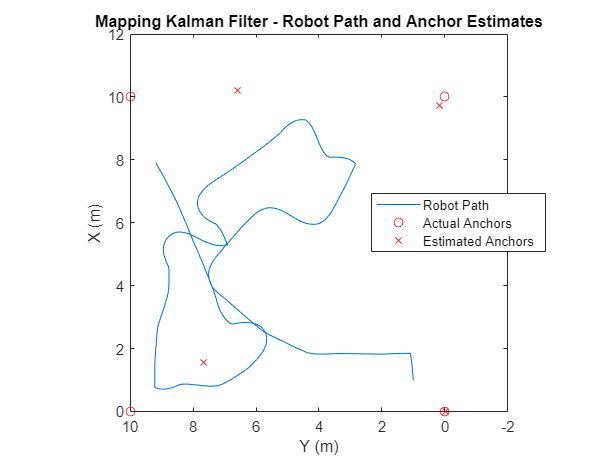



plot(robot_state_history(1,:), robot_state_history(2,:)); hold on
plot(anchor_mat(1,:), anchor_mat(2,:), 'ro'); 
plot(squeeze(state_history(1,end,:)), squeeze(state_history(2,end,:)), 'rx'); hold off
axis square
view(-90,90);
xlabel("X (m)")
ylabel("Y (m)")
title("Mapping Kalman Filter - Robot Path and Anchor Estimates")
legend("Robot Path", "Actual Anchors", "Estimated Anchors","Location","east")